% Workflow:
% 1. 
% 2. read a 3D image
% 3. preprocessing
% 4. scale E and S to 50
% 5. set up tuning
% 6. tuning parameters
% 7. attenuation correction (exponential)
% 8. check and save

% non auto: manual input z
eosin_name = "C:\Users\bear\Desktop\figure 3\Mark_and_Find 003Position003_c0.tif";
sytox_name = "C:\Users\bear\Desktop\figure 3\Mark_and_Find 003Position003_c1.tif";
image = import4d_big_nonauto([eosin_name, sytox_name], 543, 2);

Finished importing channel 1
Finished importing channel 2


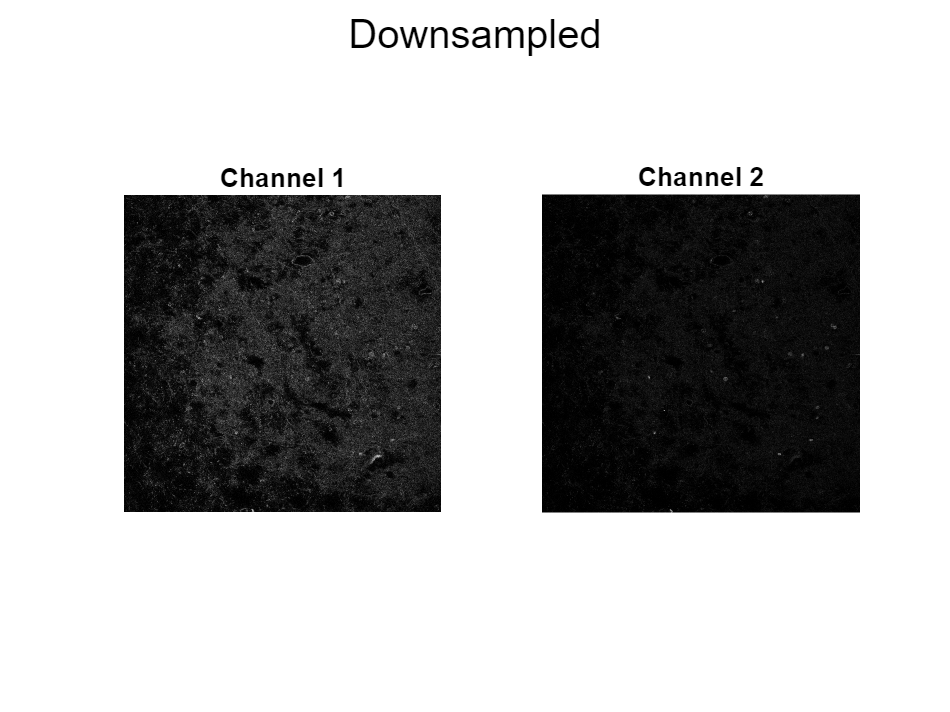

d_image = downsample_xy(image, 2);
display_first_plane(d_image, 'Downsampled');

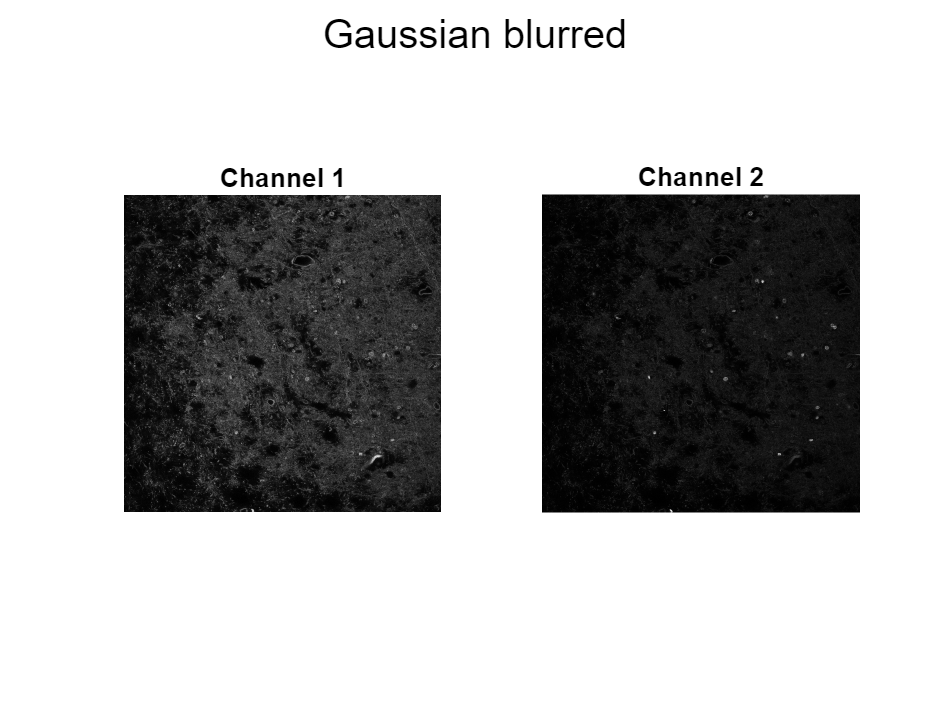

sigma_xy = 1;
sigma_z = 1;
g_image = gaussian_blur_3d(d_image, sigma_xy, sigma_z);
display_first_plane(g_image, 'Gaussian blurred');

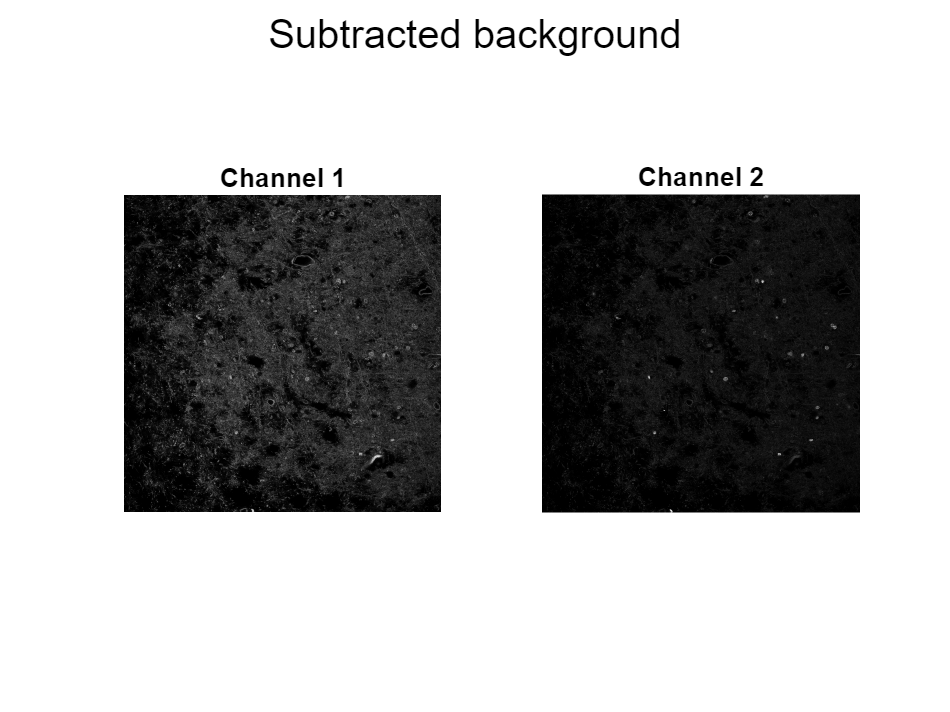

background_level = 0.2;
sb_image = subtract_background(g_image, background_level);
display_first_plane(sb_image, 'Subtracted background');

image = sb_image;
interval = 20;
analyze_image(image, interval);

Plane	Min E	Max E	Avg E	Min S	Max S	Avg S
1	0	13528	1780	0	20619	1050
21	0	21269	2083	0	17302	1215
41	0	8527	1546	0	21101	915
61	0	4595	1088	0	10792	688
81	0	3982	779	0	11183	532
101	0	2906	591	0	8152	436
121	0	2079	482	0	8148	378
141	0	1952	409	0	6111	332
161	0	1995	361	0	6302	297
181	0	1595	326	0	5459	269
201	0	1321	302	0	7326	256
221	0	1195	271	0	4976	230
241	0	1140	252	0	4918	216
261	0	1184	242	0	4731	203
281	0	1086	222	0	5803	190
301	0	978	205	0	4518	175
321	0	936	194	0	3482	164
341	0	742	179	0	3219	155
361	0	691	169	0	2262	147
381	0	687	158	0	5866	141
401	0	703	149	0	3324	132
421	0	676	140	0	2879	127
441	0	643	132	0	2855	121
461	0	644	124	0	2666	114
481	0	581	118	0	2533	109
501	0	467	112	0	2274	103
521	0	508	105	0	3569	97
541	0	510	100	0	2163	95


scale_target = 10000;
image = scale_to_10000(image, interval, scale_target);

Max Mean E: 2082.52
Max Mean S: 1215.44
Scaling Factor E: 4.8019
Scaling Factor S: 8.2275


analyze_image(image, interval);

Plane	Min E	Max E	Avg E	Min S	Max S	Avg S
1	0	64960	8549	0	169644	8637
21	0	102130	10000	0	142350	10000
41	0	40945	7422	0	173607	7529
61	0	22066	5226	0	88788	5658
81	0	19123	3742	0	92009	4380
101	0	13956	2837	0	67073	3583
121	0	9981	2317	0	67036	3107
141	0	9372	1963	0	50278	2734
161	0	9578	1736	0	51850	2441
181	0	7657	1566	0	44912	2215
201	0	6342	1448	0	60276	2105
221	0	5740	1301	0	40936	1892
241	0	5475	1208	0	40462	1780
261	0	5684	1160	0	38927	1670
281	0	5213	1064	0	47741	1560
301	0	4695	985	0	37175	1437
321	0	4497	933	0	28648	1353
341	0	3565	858	0	26486	1278
361	0	3317	813	0	18613	1208
381	0	3297	758	0	48260	1164
401	0	3375	714	0	27349	1085
421	0	3246	674	0	23689	1049
441	0	3087	635	0	23489	993
461	0	3092	597	0	21931	937
481	0	2788	567	0	20839	895
501	0	2243	536	0	18712	846
521	0	2438	503	0	29361	801
541	0	2449	480	0	17798	785


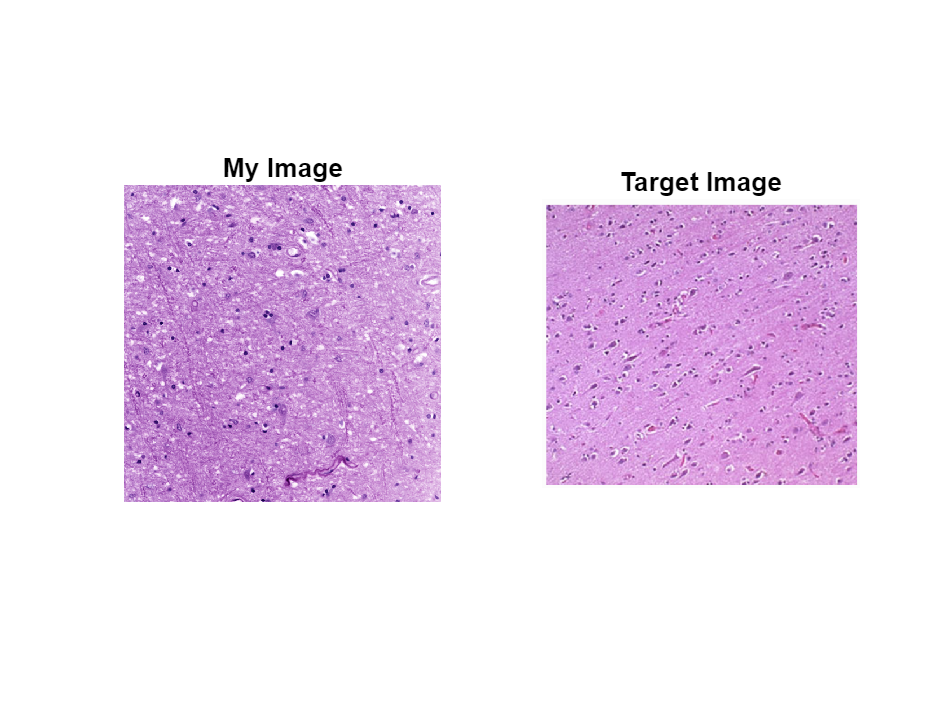

% 5. show initial image and target image
brightest_plane = load_brightest_plane(image, interval);

% default_parameters
E_to_S_base = 0;
S_to_E_base = 0;
scale_E_base = 1;
scale_S_base = 1;
default_parameters = [0, 0, 1, 1];

% display initial and target image
initial_image = convert_RGB_plane(brightest_plane, default_parameters);
target_image = im2double(imread("C:\Users\bear\Desktop\figure 3\brain.png"));
display_two_images(initial_image, target_image);

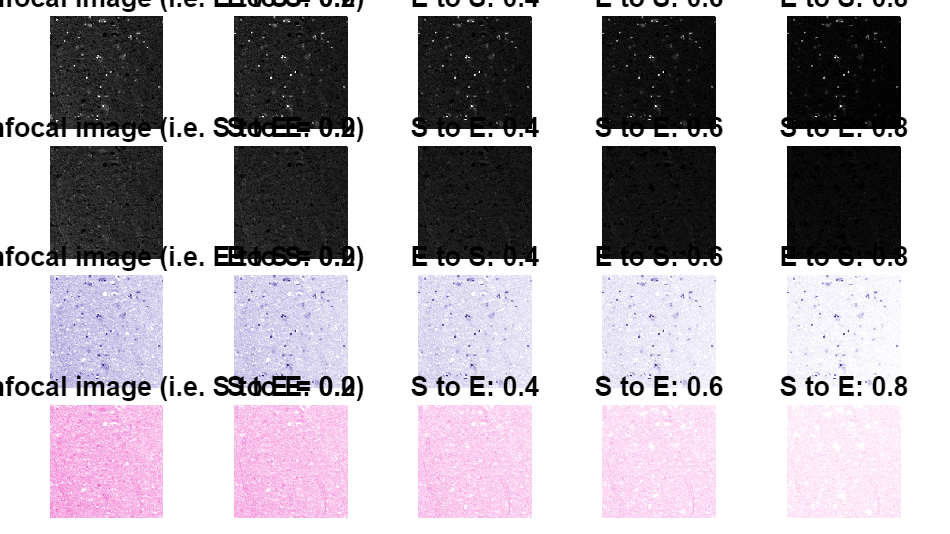

% 6.1 try crosstalk parameters
base_parameters = [0, 0, 1, 1];
E_to_S_try = [0, 0.2, 0.4, 0.6, 0.8];
S_to_E_try = [0, 0.2, 0.4, 0.6, 0.8];
crosstalk_try = [E_to_S_try; S_to_E_try];
zoom_factor = 1.5;
display_crosstalk_try(brightest_plane, base_parameters, crosstalk_try, zoom_factor);

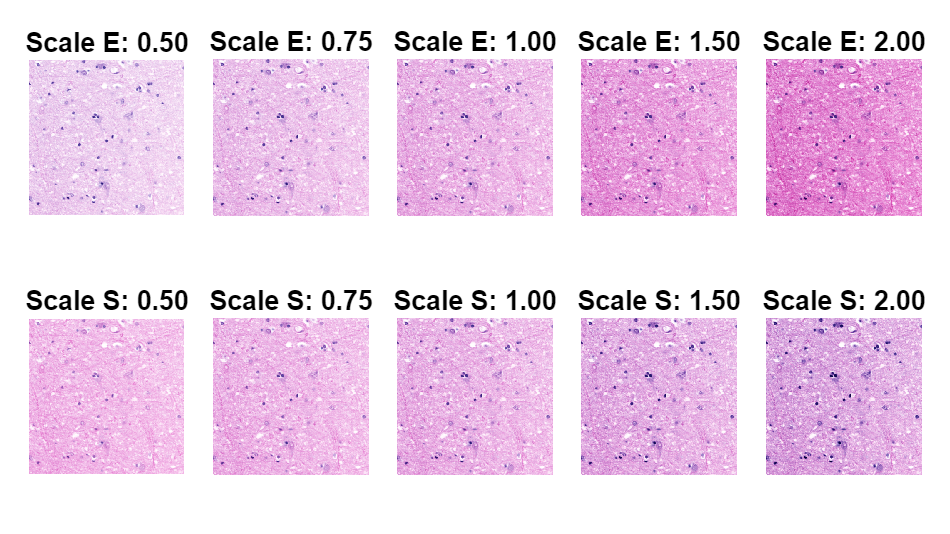

% 6.2 try scale parameters
base_parameters = [0.7, 0.2, 1, 1];
scale_E_try = [0.5, 0.75, 1, 1.5, 2];
scale_S_try = [0.5, 0.75, 1, 1.5, 2];
scale_parameters = [scale_E_try; scale_S_try];
zoom_factor = 1.5;
display_scale_try(brightest_plane, base_parameters, scale_parameters, zoom_factor);

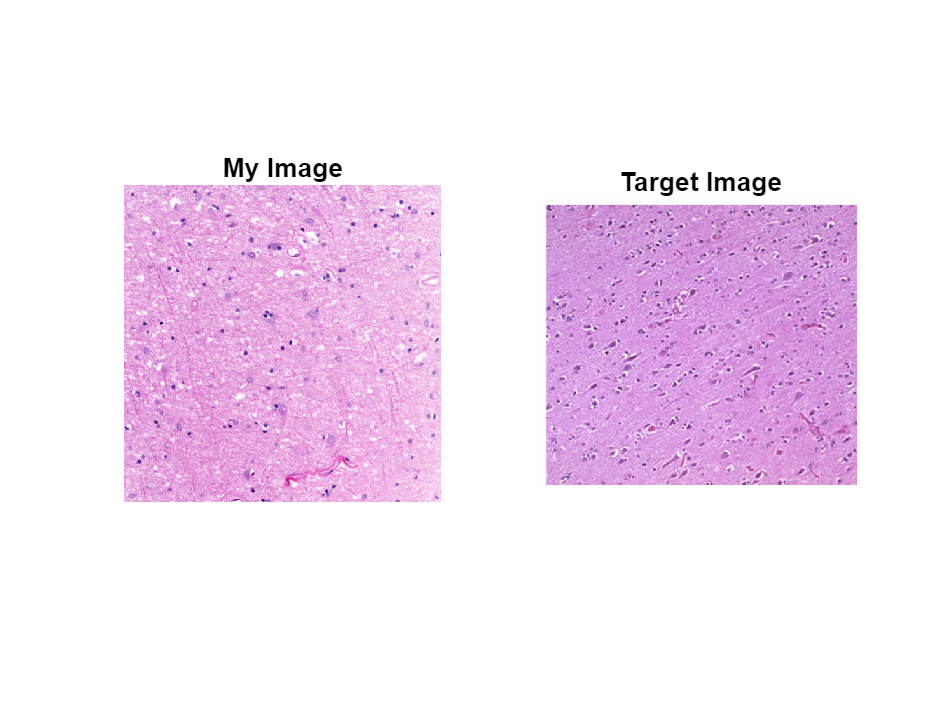

% 6.3 pick parameters
picked_parameters = [0.7, 0.2, 1.2, 1];
final_image = convert_RGB_plane(brightest_plane, picked_parameters);
display_two_images(final_image, target_image);

% 6.4 scale stack with picked parameters
spp_image = scale_stack(image, picked_parameters);
analyze_image(spp_image, interval);

Plane	Min E	Max E	Avg E	Min S	Max S	Avg S
1	0	64373	8255	0	156769	3026
21	0	104803	9603	0	121765	3124
41	0	41456	7105	0	159083	2461
61	0	22298	4919	0	81449	2086
81	0	19489	3448	0	85827	1820
101	0	14397	2556	0	62241	1643
121	0	9555	2049	0	61088	1524
141	0	7357	1716	0	46040	1395
161	0	9762	1515	0	47622	1262
181	0	6863	1361	0	42224	1153
201	0	6402	1251	0	56999	1129
221	0	5240	1123	0	37651	1017
241	0	4708	1044	0	38099	982
261	0	4847	1009	0	36715	898
281	0	5386	917	0	45490	856
301	0	4479	852	0	35623	789
321	0	3893	809	0	26539	741
341	0	3468	737	0	24515	720
361	0	2998	695	0	17541	676
381	0	3308	648	0	46387	677
401	0	3390	610	0	25854	629
421	0	2886	574	0	22647	624
441	0	2860	540	0	21942	596
461	0	2580	506	0	20321	562
481	0	2873	481	0	20041	542
501	0	2304	455	0	17529	513
521	0	2297	424	0	28139	490
541	0	2115	403	0	17061	494



Decay Coefficients:
E channel: exponential_E = -5.32e-03
S channel: exponential_S = -3.28e-03


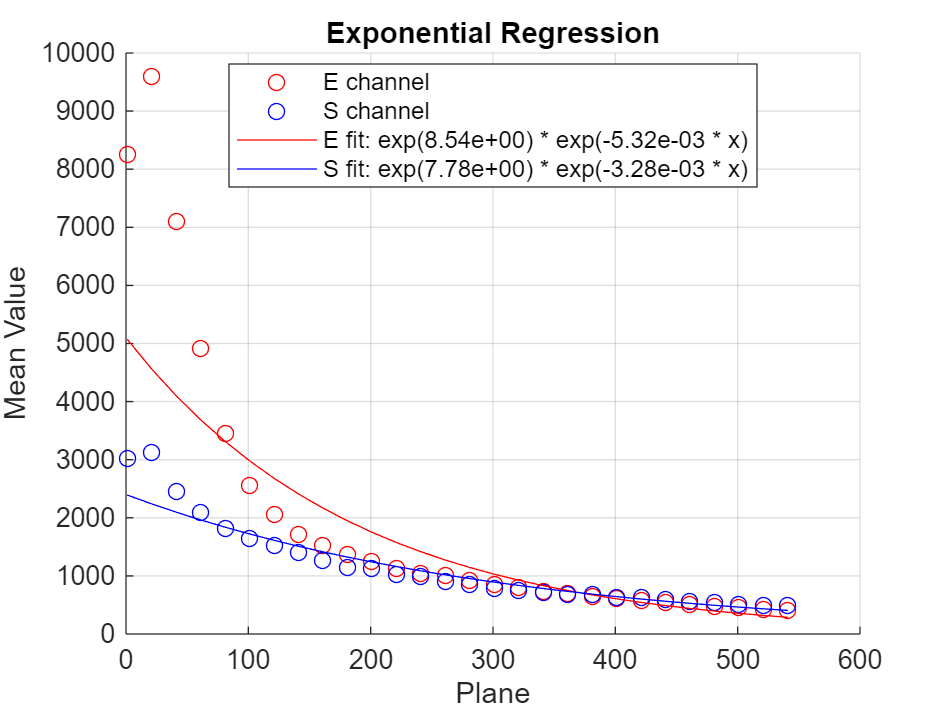

% 7. attenuation correction (exponential)
[exponential_E, exponential_S] = exponential_regression(spp_image, interval);

ac_image = attenuation_correction(spp_image, exponential_E, exponential_S);
analyze_image(ac_image, interval);

Plane	Min E	Max E	Avg E	Min S	Max S	Avg S
1	0	64373	8255	0	156769	3026
21	0	116559	10680	0	130031	3336
41	0	51277	8788	0	181414	2806
61	0	30674	6767	0	99187	2540
81	0	29818	5276	0	111614	2367
101	0	24498	4349	0	86436	2281
121	0	18083	3877	0	90594	2260
141	0	15485	3612	0	72913	2209
161	0	22852	3546	0	80537	2133
181	0	17868	3544	0	76257	2083
201	0	18537	3621	0	109928	2177
221	0	16874	3616	0	77543	2095
241	0	16861	3738	0	83791	2159
261	0	19307	4017	0	86229	2110
281	0	23858	4064	0	114092	2146
301	0	22067	4198	0	95408	2113
321	0	21330	4431	0	75903	2118
341	0	21133	4493	0	74875	2198
361	0	20318	4713	0	57211	2206
381	0	24934	4885	0	161567	2357
401	0	28421	5116	0	96160	2338
421	0	26908	5348	0	89951	2478
441	0	29660	5599	0	93070	2530
461	0	29751	5833	0	92044	2547
481	0	36854	6164	0	96937	2623
501	0	32866	6486	0	90541	2652
521	0	36445	6729	0	155211	2703
541	0	37312	7110	0	100498	2907


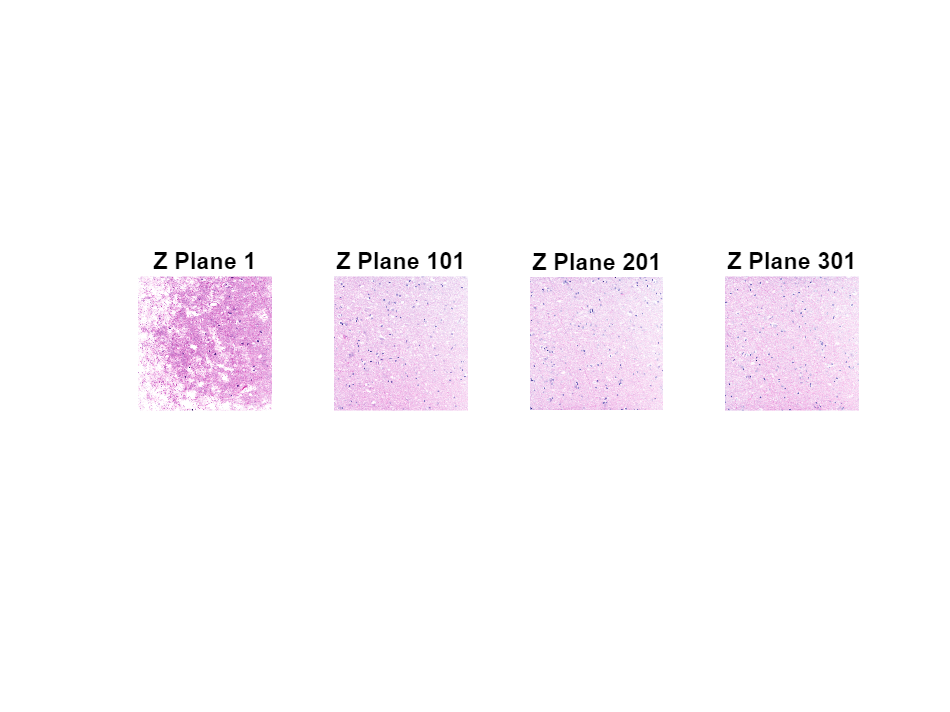

% 8.1 check image
z_index = [1, 101, 201, 301]; 
display_image(ac_image, z_index);

outname = "C:\Users\bear\Desktop\figure 3\human brain.tif";
export_rgb(ac_image, 100, outname);